% Set params
clear
N=40;
a=1;
d=-0.01;
xbar=1;
umax=8;
gamma=10^-2;
delta=10^-2;

f_part = @(u_var) additional_bounds(u_var, N, a, d, xbar, umax, gamma, delta);
grad_f = @(u_var) additional_bounds_gradient(u_var, N, a, d, xbar, umax, gamma, delta);
u_min = constant_descent(1, (umax/2)*ones(N,1), grad_f, 10^-3);

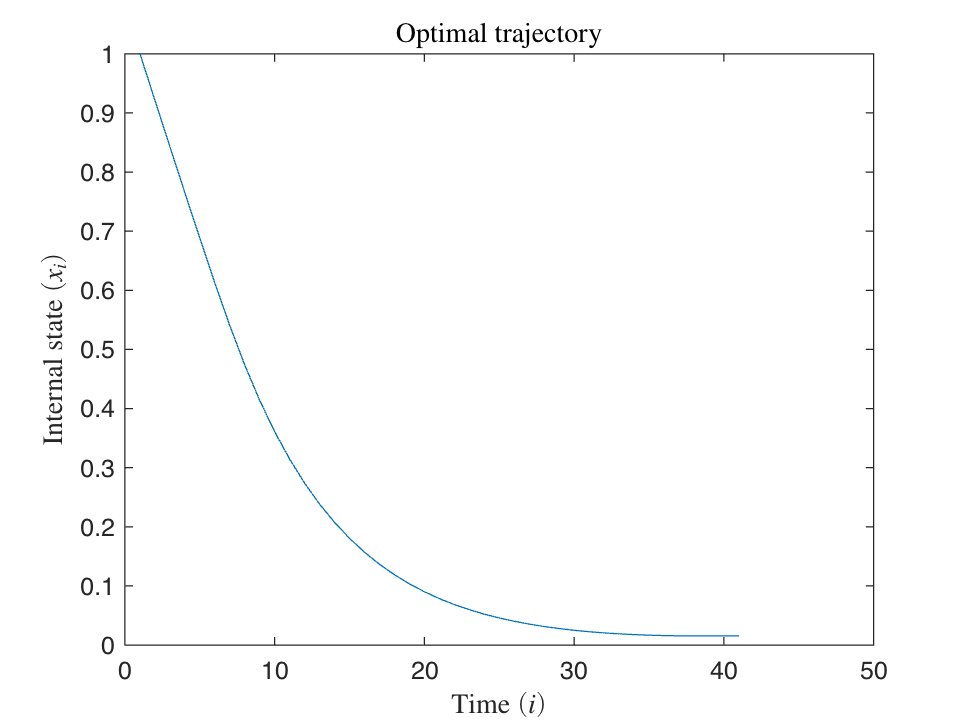

A = genA(d,a,N);
b = genb(xbar,a,N);
plot([xbar;get_x(A,u_min,b)])
title("Optimal trajectory", "Interpreter","latex")
xlabel("Time $(i)$", 'Interpreter','latex')
ylabel("Internal state $\left(x_i\right)$", 'Interpreter','latex');

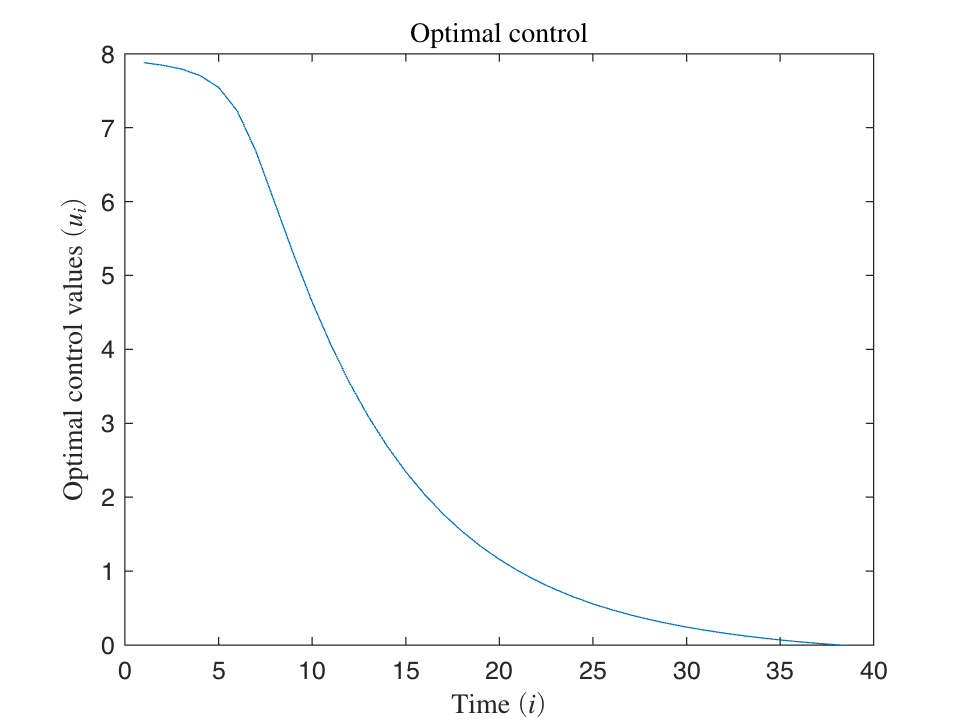

plot(u_min)
title("Optimal control", "Interpreter", "latex")
axis([0 40 0 8])
xlabel("Time $(i)$", 'Interpreter','latex')
ylabel("Optimal control values $\left(u_i\right)$", 'Interpreter','latex');